# Code 2: Regression Bias in Solar Wind Measurements

by Nithin Sivadas

April 19th, 2022

This code compares ACE and WIND solar wind measurements, and carries out non-linear regression analysis to demonstrate regression bias due to random uncertainty in solar wind measurements. 

Refer: Sivadas et al., 2022(a) Regression to the Mean in Solar Wind Measurements. *In preparation. (See section 3)*

*Required packages: *

*Circular Statistics Toolbox (Directional Statistics) *[[Link]](https://www.mathworks.com/matlabcentral/fileexchange/10676-circular-statistics-toolbox-directional-statistics)

    P. Berens, CircStat: A Matlab Toolbox for Circular Statistics, Journal of Statistical Software, Volume 31, Issue 10, 2009 [http://www.jstatsoft.org/v31/i10](http://www.jstatsoft.org/v31/i10)

%Specify the folder where all the data is stored in DataDir. Extract data from the
%following zip file: https://github.com/nithinsivadas/regression-bias/Data.zip
DataDir = 'C:\Users\nithin\Documents\GitHub\regression-bias\Data\'; 
windDataFolder = [DataDir,'omni_components\'];

From OmniWeb [WIND & ACE Spacecraft specific 1-min resolution measurements](https://spdf.gsfc.nasa.gov/pub/data/omni/high_res_omni/sc_specific/) (NASA)

setExportFig = 0;
outputFolder = 'G:\My Drive\Research\Projects\Sivadas_2022g\Figures\';

[wind, ace, geotail, indices] = initialize_spacecrafts(windDataFolder);

% Selecting duration of interest
indices.aceTime = find((ace.datetime>=datetime(1998,1,1))&(ace.datetime<datetime(2022,1,1)));
indices.windTime = find((wind.datetime>=datetime(1998,1,1))&(wind.datetime<datetime(2022,1,1)));

## Fig 7: Regression bias in Solar Wind Velocity $V_y$ and $V_z$

aceVz = ace.VzGSE(intersect(indices.awI,indices.aceTime),:);
windVz = wind.VzGSE(intersect(indices.waI,indices.windTime),:);
xBin1=linspace(-300,300,50);

% Calculating the condtional expectation of WIND-Vz given ACE-Vz, and
% vice-versa.
E_wVz_g_aVz = create_curve(windVz,aceVz,xBin1);
E_aVz_g_wVz = create_curve(aceVz,windVz,xBin1);

aceVy = ace.VyGSE(intersect(indices.awI,indices.aceTime),:);
windVy = wind.VyGSE(intersect(indices.waI,indices.windTime),:);
xBin2=linspace(-250,300,50);

% Calculating the condtional expectation of WIND-Vy given ACE-Vy, and
% vice-versa.
E_wVy_g_aVy = create_curve(windVy,aceVy,xBin2);
E_aVy_g_wVy = create_curve(aceVy,windVy,xBin2);

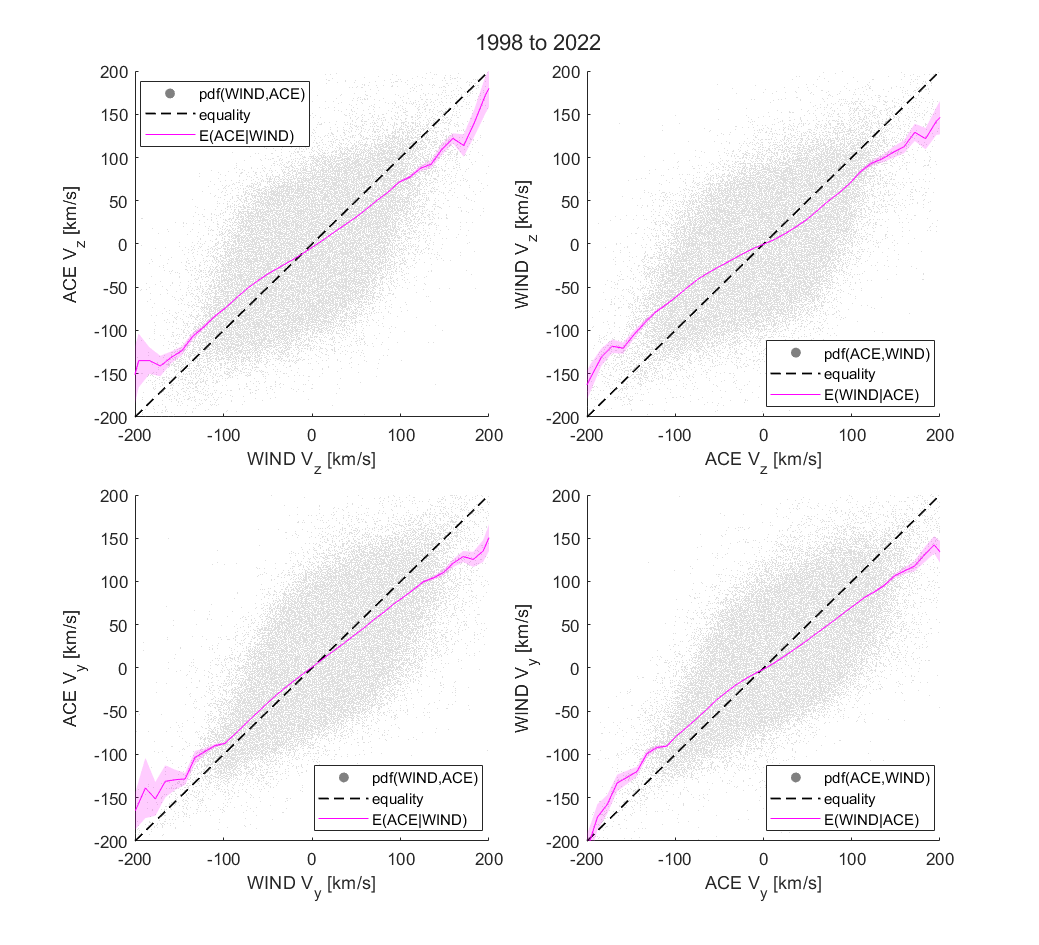

fig1 = figure;
resize_figure(fig1,200,220);
t=tiledlayout(2,2,"TileSpacing","compact");
xBin1=linspace(-300,300,50);
xBin2=linspace(-250,300,50);

% Plotting the condtional expectations
title(t,'1998 to 2022');

nexttile
plot_type1(windVz,'WIND',aceVz,'ACE',E_aVz_g_wVz,'V_z [km/s]',xBin1);
xlim([-200,200]);
ylim([-200,200]);


nexttile
plot_type1(aceVz,'ACE',windVz,'WIND', E_wVz_g_aVz,'V_z [km/s]',xBin1);
xlim([-200,200]);
ylim([-200,200]);


nexttile
plot_type1(windVy,'WIND',aceVy,'ACE',E_aVy_g_wVy,'V_y [km/s]',xBin2);
xlim([-200,200]);
ylim([-200,200]);


nexttile
plot_type1(aceVy,'ACE',windVy,'WIND', E_wVy_g_aVy,'V_y [km/s]',xBin2);
xlim([-200,200]);
ylim([-200,200]);



if setExportFig
export_fig([outputFolder,'FigureM1.png'], ...
    '-r600','-png','-nocrop',fig1);
export_fig([outputFolder,'FigureM1.pdf'], ...
    '-r600','-pdf','-nocrop',fig1);
end

## Fig 8: Regression bias in IMF $B_z$

indices.aceTime = find((ace.datetime>=datetime(2002,1,1))&(ace.datetime<datetime(2002,12,31)));
indices.windTime = find((wind.datetime>=datetime(2002,1,1))&(wind.datetime<datetime(2002,12,31)));

aceBz = ace.BzGSM(intersect(indices.awI,indices.aceTime),:);
windBz = wind.BzGSM(intersect(indices.waI,indices.windTime),:);
xBin1=linspace(-50,50,50);

E_wBz_g_aBz = create_curve(windBz,aceBz,xBin1);
E_aBz_g_wBz = create_curve(aceBz,windBz,xBin1);

% Calculating impact parameter
relXGSE = -ace.X_GSE(intersect(indices.awI,indices.aceTime),:)+wind.X_GSE(intersect(indices.waI,indices.windTime),:);
relYGSE = -ace.Y_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Y_GSE(intersect(indices.waI,indices.windTime),:);
relZGSE = -ace.Z_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Z_GSE(intersect(indices.waI,indices.windTime),:);

Dij = sqrt((relYGSE + relXGSE./13).^2 + relZGSE.^2);

aceBz1 = ace.BzGSM(intersect(indices.awI,indices.aceTime   ),:);
windBz1 = wind.BzGSM(intersect(indices.waI,indices.windTime),:);
xBin1=linspace(-50,50,50);

E_wBz_g_aBz1 = create_curve(windBz1(Dij<60),aceBz1(Dij<60),xBin1);
E_aBz_g_wBz1 = create_curve(aceBz1(Dij<60),windBz1(Dij<60),xBin1);

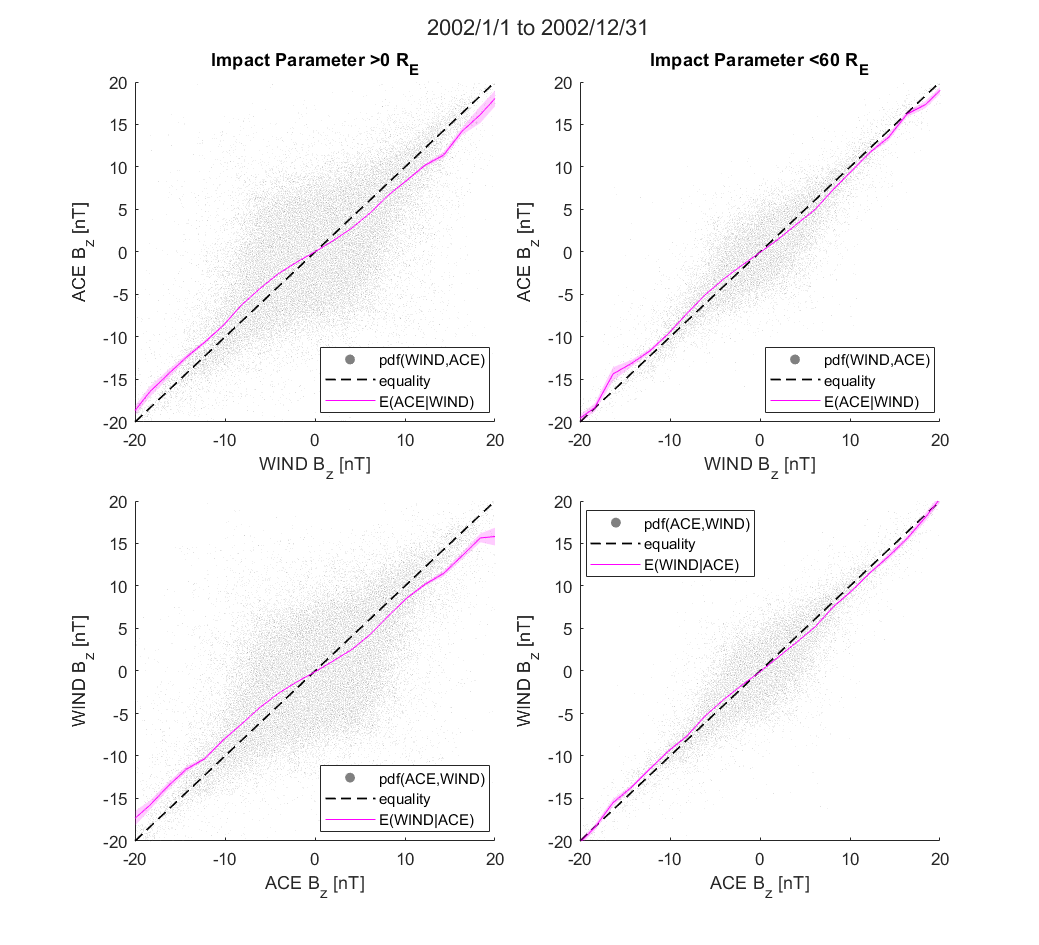

fig2 = figure;
resize_figure(fig2,200,220);
t2 = tiledlayout(2,2,"TileSpacing","compact");
xBin1=linspace(-50,50,50);
title(t2,'2002/1/1 to 2002/12/31');

nexttile
plot_type1(windBz,'WIND',aceBz,'ACE',E_aBz_g_wBz,'B_z [nT]',xBin1);
title('Impact Parameter >0 R_E');
xlim([-20,20]);
ylim([-20,20]);

nexttile
plot_type1(windBz1(Dij<60),'WIND',aceBz1(Dij<60),'ACE',E_aBz_g_wBz1,'B_z [nT]',xBin1);
title('Impact Parameter <60 R_E');
xlim([-20,20]);
ylim([-20,20]);

nexttile
plot_type1(aceBz,'ACE',windBz,'WIND', E_wBz_g_aBz,'B_z [nT]',xBin1);
xlim([-20,20]);
ylim([-20,20]);

nexttile
plot_type1(aceBz1(Dij<60),'ACE',windBz1(Dij<60),'WIND', E_wBz_g_aBz1,'B_z [nT]',xBin1);
xlim([-20,20]);
ylim([-20,20]);



if setExportFig
export_fig([outputFolder,'FigureM2.png'], ...
    '-r600','-png','-nocrop',fig2);
export_fig([outputFolder,'FigureM2.pdf'], ...
    '-r600','-pdf','-nocrop',fig2);
end

## Fig 9: Regression bias in Proton Number Density $N$

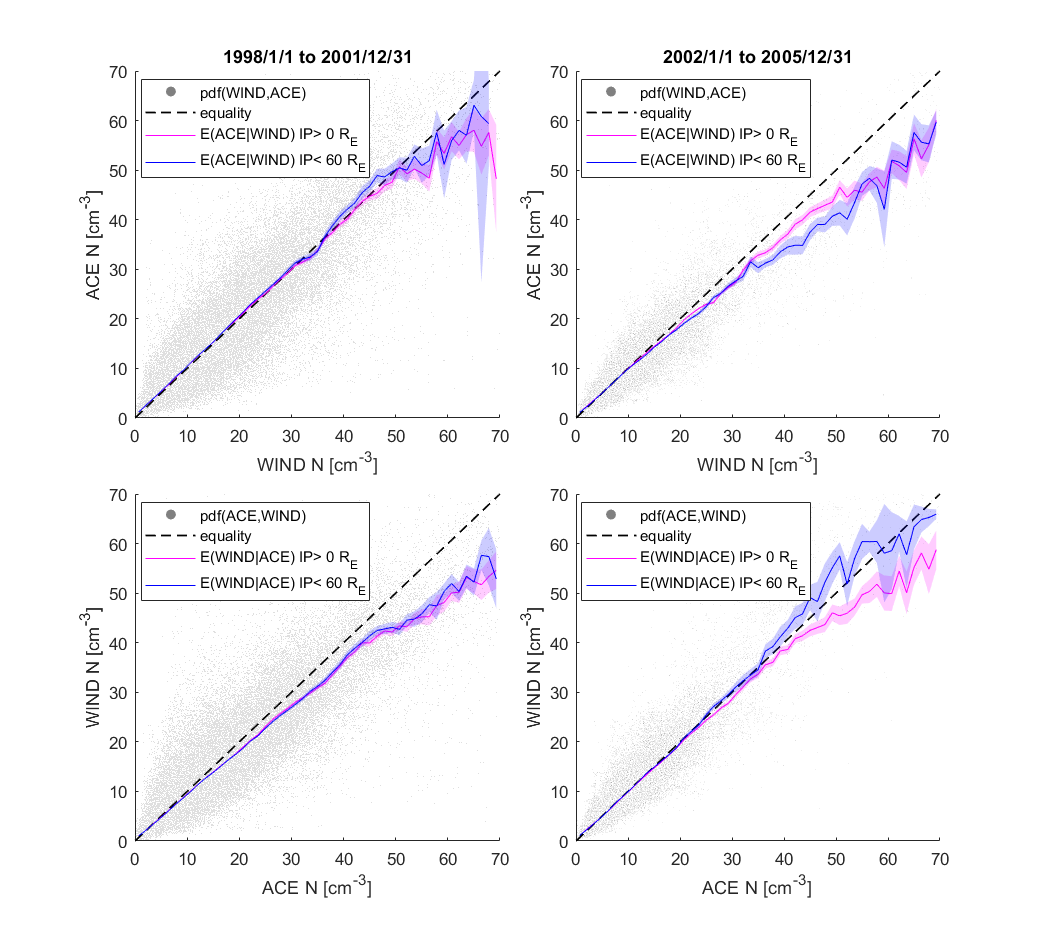

indices.aceTime = find((ace.datetime>=datetime(1998,1,1))&(ace.datetime<datetime(2001,12,31)));
indices.windTime = find((wind.datetime>=datetime(1998,1,1))&(wind.datetime<datetime(2001,12,31)));

aceD = ace.density(intersect(indices.awI,indices.aceTime),:);
windD = wind.density(intersect(indices.waI,indices.windTime),:);
xBin1=linspace(0,70,50);

E_wD_g_aD = create_curve(windD,aceD,xBin1);
E_aD_g_wD = create_curve(aceD,windD,xBin1);

IP = 60;
relXGSE = -ace.X_GSE(intersect(indices.awI,indices.aceTime),:)+wind.X_GSE(intersect(indices.waI,indices.windTime),:);
relYGSE = -ace.Y_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Y_GSE(intersect(indices.waI,indices.windTime),:);
relZGSE = -ace.Z_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Z_GSE(intersect(indices.waI,indices.windTime),:);

Dij = sqrt((relYGSE + relXGSE./13).^2 + relZGSE.^2);

E_wD_g_aD1 = create_curve(windD(Dij<IP),aceD(Dij<IP),xBin1);
E_aD_g_wD1 = create_curve(aceD(Dij<IP),windD(Dij<IP),xBin1);

% A different time

indices.aceTime1 = find((ace.datetime>=datetime(2002,1,1))&(ace.datetime<datetime(2005,12,31)));
indices.windTime1 = find((wind.datetime>=datetime(2002,1,1))&(wind.datetime<datetime(2005,12,31)));

aceD1 = ace.density(intersect(indices.awI,indices.aceTime1),:);
windD1 = wind.density(intersect(indices.waI,indices.windTime1),:);
xBin1=linspace(0,70,50);

E_wD_g_aDF = create_curve(windD1,aceD1,xBin1);
E_aD_g_wDF = create_curve(aceD1,windD1,xBin1);

IP = 60;
relXGSE1 = -ace.X_GSE(intersect(indices.awI,indices.aceTime1),:)+wind.X_GSE(intersect(indices.waI,indices.windTime1),:);
relYGSE1 = -ace.Y_GSE(intersect(indices.awI,indices.aceTime1),:)+wind.Y_GSE(intersect(indices.waI,indices.windTime1),:);
relZGSE1 = -ace.Z_GSE(intersect(indices.awI,indices.aceTime1),:)+wind.Z_GSE(intersect(indices.waI,indices.windTime1),:);
%SQRT {[Yi-Yj + (Xi-Xj)/13]**2 + (Zi-Zj)**2} https://omniweb.gsfc.nasa.gov/ftpbrowser/impact_ii.html
Dij1 = sqrt((relYGSE1 + relXGSE1./13).^2 + relZGSE1.^2);

E_wD_g_aDF1 = create_curve(windD1(Dij1<IP),aceD1(Dij1<IP),xBin1);
E_aD_g_wDF1 = create_curve(aceD1(Dij1<IP),windD1(Dij1<IP),xBin1);

fig3 = figure;
resize_figure(fig3,200,220);
t3 = tiledlayout(2,2,"TileSpacing","compact");
xBin1=linspace(0,70,50);


nexttile

[p1,p2,p3]=plot_type1(windD,'WIND',aceD,'ACE',E_aD_g_wD,'N [cm^{-3}]',xBin1);
title('1998/1/1 to 2001/12/31');
hold on;
p4=plot_curve(E_aD_g_wD1,'b');
legend([p1,p2,p3,p4],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E'})
xlim([0,70]);
ylim([0,70]);

nexttile

[p1,p2,p3]=plot_type1(windD1(Dij1<IP),'WIND',aceD1(Dij1<IP),'ACE',E_aD_g_wDF,'N [cm^{-3}]',xBin1);
title('2002/1/1 to 2005/12/31');
hold on;
p4=plot_curve(E_aD_g_wDF1,'b');
legend([p1,p2,p3,p4],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E'})
xlim([0,70]);
ylim([0,70]);

nexttile
[p1,p2,p3]=plot_type1(aceD,'ACE',windD,'WIND', E_wD_g_aD,'N [cm^{-3}]',xBin1);
hold on;
p4=plot_curve(E_wD_g_aD1,'b');
legend([p1,p2,p3,p4],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E'})
xlim([0,70]);
ylim([0,70]);

nexttile
[p1,p2,p3]=plot_type1(aceD1(Dij1<IP),'ACE',windD1(Dij1<IP),'WIND', E_wD_g_aDF,'N [cm^{-3}]',xBin1);
hold on;
p4=plot_curve(E_wD_g_aDF1,'b');
legend([p1,p2,p3,p4],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E'})
xlim([0,70]);
ylim([0,70]);

if setExportFig
export_fig([outputFolder,'FigureM3.png'], ...
    '-r600','-png','-nocrop',fig3);
export_fig([outputFolder,'FigureM3.pdf'], ...
    '-r600','-pdf','-nocrop',fig3);
end

## Fig 10: IMF Clock Angle $B_y$/$B_z$ and $\theta_{cl}$  

indices.aceTime = find((ace.datetime>=datetime(1998,1,1))&(ace.datetime<datetime(2021,12,31)));
indices.windTime = find((wind.datetime>=datetime(1998,1,1))&(wind.datetime<datetime(2021,12,31)));

% aceByz = ace.ByGSM(intersect(indices.awI,indices.aceTime),:)./ace.BzGSM(intersect(indices.awI,indices.aceTime),:);
% windByz = wind.ByGSM(intersect(indices.waI,indices.windTime),:)./wind.BzGSM(intersect(indices.waI,indices.windTime),:);
aceByz = ace.ByGSM(indices.awI,:)./ace.BzGSM(indices.awI,:);
windByz = wind.ByGSM(indices.waI,:)./wind.BzGSM(indices.waI,:);
aceByz(isinf(aceByz))=nan;
windByz(isinf(windByz))=nan;

aceCL = atan2(ace.ByGSM(indices.awI,:),ace.BzGSM(indices.awI,:)); %in radians
windCL = atan2(wind.ByGSM(indices.waI,:),wind.BzGSM(indices.waI,:)); %in radians

xBin1=[tand(-89.999),-20:0.5:20,tand(89.999)];


E_wByz_g_aByz = create_curve(windByz,aceByz,xBin1);
E_aByz_g_wByz = create_curve(aceByz,windByz,xBin1);

% Calculating impact parameter
% relXGSE = -ace.X_GSE(intersect(indices.awI,indices.aceTime),:)+wind.X_GSE(intersect(indices.waI,indices.windTime),:);
% relYGSE = -ace.Y_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Y_GSE(intersect(indices.waI,indices.windTime),:);
% relZGSE = -ace.Z_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Z_GSE(intersect(indices.waI,indices.windTime),:);

relXGSE = -ace.X_GSE(indices.awI,:)+wind.X_GSE(indices.waI,:);
relYGSE = -ace.Y_GSE(indices.awI,:)+wind.Y_GSE(indices.waI,:);
relZGSE = -ace.Z_GSE(indices.awI,:)+wind.Z_GSE(indices.waI,:);
%SQRT {[Yi-Yj + (Xi-Xj)/13]**2 + (Zi-Zj)**2} https://omniweb.gsfc.nasa.gov/ftpbrowser/impact_ii.html
Dij = sqrt((relYGSE + relXGSE./13).^2 + relZGSE.^2);

E_wByz_g_aByz1 = create_curve(windByz(Dij<60),aceByz(Dij<60),xBin1);
E_aByz_g_wByz1 = create_curve(aceByz(Dij<60),windByz(Dij<60),xBin1);

% Using directional statistics
xBin2 = deg2rad(-180:2:180);
E_wCL_g_aCL = create_curve(windCL,aceCL,xBin2,2);
E_aCL_g_wCL = create_curve(aceCL,windCL,xBin2,2);
E_wCL_g_aCL1 = create_curve(windCL(Dij<60),aceCL(Dij<60),xBin2,2);
E_aCL_g_wCL1 = create_curve(aceCL(Dij<60),windCL(Dij<60),xBin2,2);


% Sin^2(theta/2)
aceSCL = (sin(aceCL./2)).^2;
windSCL = (sin(windCL./2)).^2;
xBin3 = linspace(0,1,40);
E_wSCL_g_aSCL = create_curve(windSCL,aceSCL,xBin3);
E_aSCL_g_wSCL = create_curve(aceSCL,windSCL,xBin3);
E_wSCL_g_aSCL1 = create_curve(windSCL(Dij<60),aceSCL(Dij<60),xBin3);
E_aSCL_g_wSCL1 = create_curve(aceSCL(Dij<60),windSCL(Dij<60),xBin3);

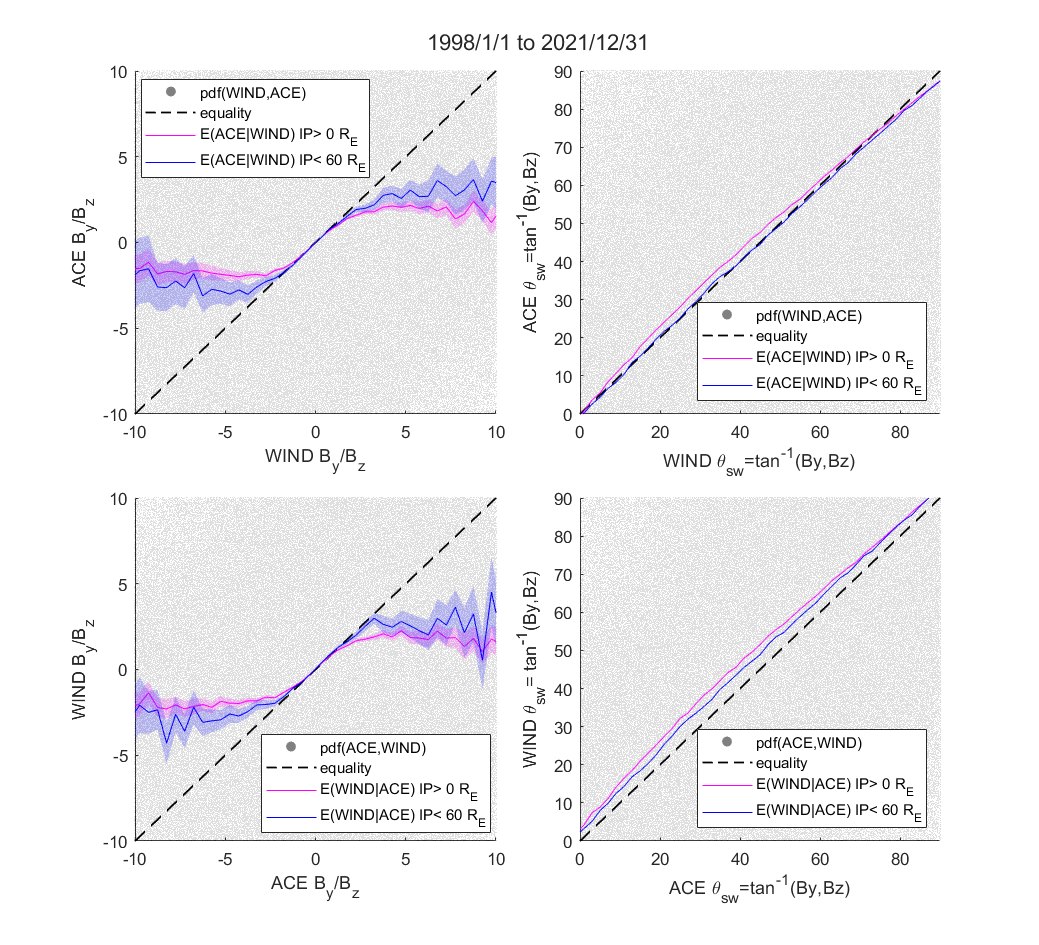

fig4_1 = figure;
resize_figure(fig4_1,200,220);
t4 = tiledlayout(2,2,"TileSpacing","compact");
xBin1=tand(-89.9:1:89.9);
title(t4,'1998/1/1 to 2021/12/31');

nexttile
[p1,p2,p3]=plot_type1(windByz,'WIND',aceByz,'ACE',E_aByz_g_wByz,'B_y/B_z',xBin1);
hold on;
p4 = plot_curve(E_aByz_g_wByz1,'b');
legend([p1,p2,p3,p4],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E'})
xlim([-10,10]);
ylim([-10,10]);

nexttile
    xBin2 = wrapTo180(rad2deg(E_aCL_g_wCL.XBins));
    label1 = 'WIND \theta_{sw}=tan^{-1}(By,Bz)'; label2 = 'ACE \theta_{sw}=tan^{-1}(By,Bz)'; 
    p1 = scatter(wrapTo180(rad2deg(windCL)),wrapTo180(rad2deg(aceCL)),0.1,0.5.*[1 1 1],'filled');
    hold on;
    p2 = plot(xBin2, xBin2, '--k','LineWidth',1);
    hold on;
    p3 = plot(xBin2,wrapTo180(rad2deg(E_aCL_g_wCL.YgX)),'m');
    hold on;
    p4 = plot(xBin2,wrapTo180(rad2deg(E_aCL_g_wCL1.YgX)),'b');
    xlabel(label1);
    ylabel(label2);
    xlim([0,90]);
    ylim([0,90]);
    legend([p1,p2,p3,p4],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E'},'Location','southeast');


nexttile
[p1,p2,p3]=plot_type1(aceByz,'ACE',windByz,'WIND', E_wByz_g_aByz,'B_y/B_z',xBin1);
hold on;
p4 = plot_curve(E_wByz_g_aByz1,'b');
legend([p1,p2,p3,p4],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E'})
xlim([-10,10]);
ylim([-10,10]);

nexttile
    xBin2 = wrapTo180(rad2deg(E_wCL_g_aCL.XBins));
    label1 = 'ACE \theta_{sw}=tan^{-1}(By,Bz)'; label2 = 'WIND \theta_{sw}= tan^{-1}(By,Bz)'; 
    p1 = scatter(wrapTo180(rad2deg(aceCL)),wrapTo180(rad2deg(windCL)),0.1,0.5.*[1 1 1],'filled');
    hold on;
    p2 = plot(xBin2, xBin2, '--k','LineWidth',1);
    hold on;
    p3 = plot(xBin2,wrapTo180(rad2deg(E_wCL_g_aCL.YgX)),'m');
    hold on;
    p4 = plot(xBin2,wrapTo180(rad2deg(E_wCL_g_aCL1.YgX)),'b');
    xlabel(label1);
    ylabel(label2);
    xlim([0,90]);
    ylim([0,90]);
    legend([p1,p2,p3,p4],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E'},'Location','southeast');



if setExportFig
export_fig([outputFolder,'FigureM4_1.png'], ...
    '-r600','-png','-nocrop',fig4_1);
export_fig([outputFolder,'FigureM4_1.pdf'], ...
    '-r600','-pdf','-nocrop',fig4_1);
end

## Fig S1: Plot of $\sin^2 \frac{\theta_{\textrm{cl}} }{2}$

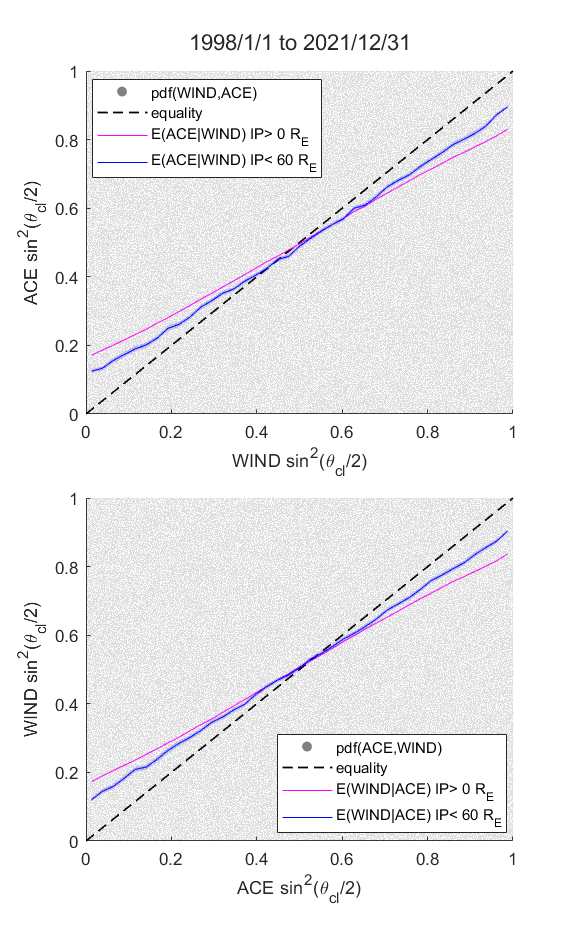

figS1 = figure;
resize_figure(figS1,200,120);
ts1 = tiledlayout(2,1,"TileSpacing","compact");

title(ts1,'1998/1/1 to 2021/12/31');

nexttile
[p1,p2,p3]=plot_type1(windSCL,'WIND',aceSCL,'ACE',E_aSCL_g_wSCL,'sin^2(\theta_{cl}/2)',xBin3);
hold on;
p4 = plot_curve(E_aSCL_g_wSCL1,'b');
legend([p1,p2,p3,p4],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E'})
xlim([0,1]);
ylim([0,1]);

nexttile
[p1,p2,p3]=plot_type1(aceSCL,'ACE',windSCL,'WIND',E_wSCL_g_aSCL,'sin^2(\theta_{cl}/2)',xBin3);
hold on;
p4 = plot_curve(E_wSCL_g_aSCL1,'b');
legend([p1,p2,p3,p4],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E'})
xlim([0,1]);
ylim([0,1]);

if setExportFig
export_fig([outputFolder,'FigureS1.png'], ...
    '-r600','-png','-nocrop',figS1);
export_fig([outputFolder,'FigureS1.pdf'], ...
    '-r600','-pdf','-nocrop',figS1);
end

## Fig 11: Polar plots of $\theta_{cl}$ to explain the regression to the mean effect here

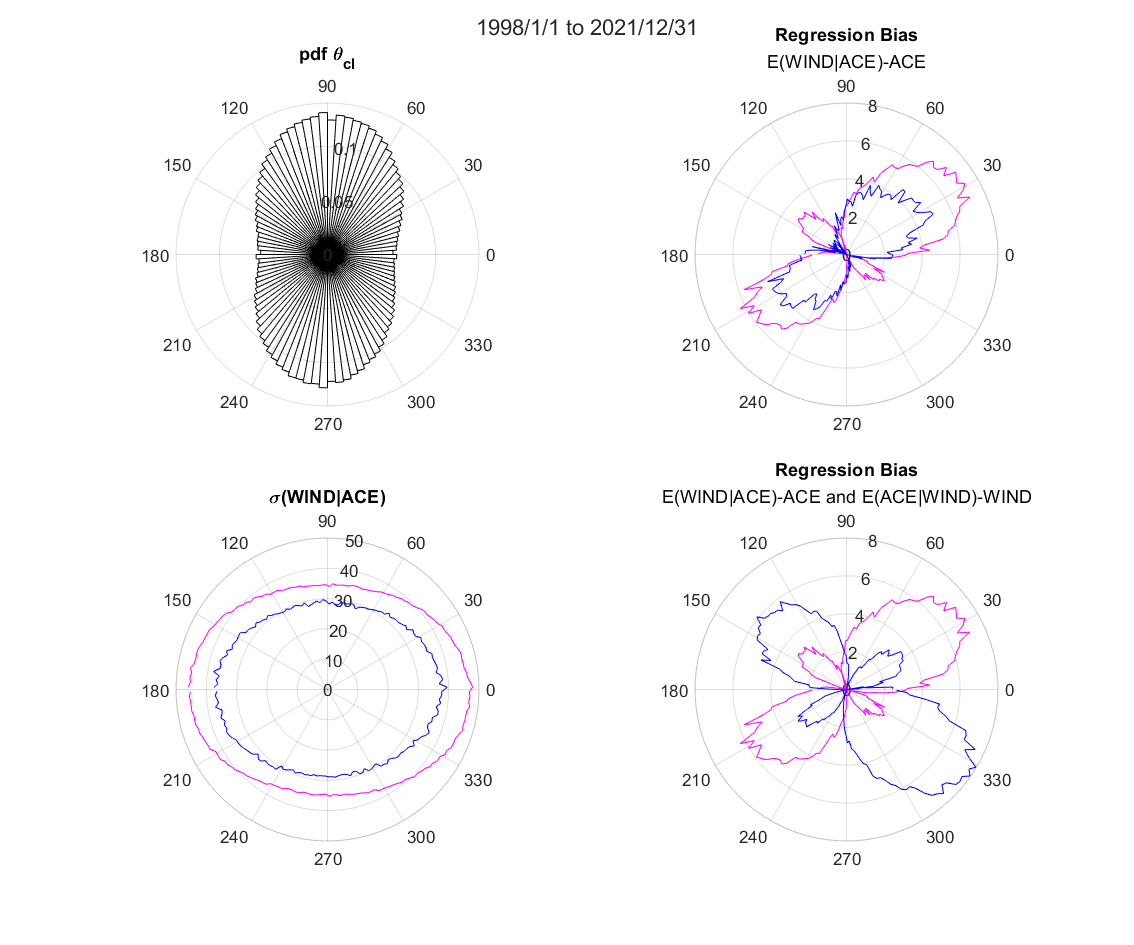

fig4_2= figure; 
resize_figure(fig4_2,200,240);
t4_2 = tiledlayout(2,2);
title(t4_2,'1998/1/1 to 2021/12/31');

nexttile
polarhistogram(aceCL,100,'Normalization','pdf','FaceColor','none');
title('pdf \theta_{cl}')

nexttile
polarplot(((E_wCL_g_aCL.XBins)),rad2deg(circ_dist(E_wCL_g_aCL.YgX,E_wCL_g_aCL.XBins)),'-m');
hold on;
polarplot(((E_wCL_g_aCL1.XBins)),rad2deg(circ_dist(E_wCL_g_aCL1.YgX,E_wCL_g_aCL1.XBins)),'-b');
title('Regression Bias','E(WIND|ACE)-ACE');

nexttile
polarplot((E_wCL_g_aCL.XBins),rad2deg(E_wCL_g_aCL.stdYgX),'-m'); 
hold on; 
polarplot((E_wCL_g_aCL1.XBins),rad2deg(E_wCL_g_aCL1.stdYgX),'-b');
title('\sigma(WIND|ACE)');

nexttile
polarplot(((E_wCL_g_aCL.XBins)),rad2deg(circ_dist(E_wCL_g_aCL.YgX,E_wCL_g_aCL.XBins)),'-m');
hold on;
polarplot(((E_aCL_g_wCL.XBins)),rad2deg(circ_dist(E_aCL_g_wCL.YgX,E_aCL_g_wCL.XBins)),'-b');
title('Regression Bias','E(WIND|ACE)-ACE and E(ACE|WIND)-WIND');


if setExportFig
export_fig([outputFolder,'FigureM4_2.png'], ...
    '-r600','-png','-nocrop',fig4_2);
export_fig([outputFolder,'FigureM4_2.pdf'], ...
    '-r600','-pdf','-nocrop',fig4_2);
end

## Merging Electric Field Em (Not shown in the paper)

indices.aceTime = find((ace.datetime>=datetime(2002,1,1))&(ace.datetime<datetime(2002,12,31)));
indices.windTime = find((wind.datetime>=datetime(2002,1,1))&(wind.datetime<datetime(2002,12,31)));

indices.windTime1 = find((wind.datetime>=datetime(2002,1,1))&(wind.datetime<datetime(2002,12,31)));
indices.geoTime1 = find((geotail.datetime>=datetime(2002,1,1))&(geotail.datetime<datetime(2002,12,31)));

aceEm = ace.E_kl(intersect(indices.awI,indices.aceTime),:).*10^-3;
windEm = wind.E_kl(intersect(indices.waI,indices.windTime),:).*10^-3;
% aceByz = ace.ByGSM(indices.awI,:)./ace.BzGSM(indices.awI,:);
% windByz = wind.ByGSM(indices.waI,:)./wind.BzGSM(indices.waI,:);

geoEm1 = geotail.E_kl(intersect(indices.gwI,indices.geoTime1),:).*10^-3;
windEm1 = wind.E_kl(intersect(indices.wgI,indices.windTime1),:).*10^-3;


xBin1=0:1:40;

E_wEm_g_aEm = create_curve(windEm,aceEm,xBin1);
E_aEm_g_wEm = create_curve(aceEm,windEm,xBin1);

E_wEm_g_gEm = create_curve(windEm1,geoEm1,xBin1);
E_gEm_g_wEm = create_curve(geoEm1,windEm1,xBin1);


% Calculating impact parameter
relXGSE = -ace.X_GSE(intersect(indices.awI,indices.aceTime),:)+wind.X_GSE(intersect(indices.waI,indices.windTime),:);
relYGSE = -ace.Y_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Y_GSE(intersect(indices.waI,indices.windTime),:);
relZGSE = -ace.Z_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Z_GSE(intersect(indices.waI,indices.windTime),:);

%SQRT {[Yi-Yj + (Xi-Xj)/13]**2 + (Zi-Zj)**2} https://omniweb.gsfc.nasa.gov/ftpbrowser/impact_ii.html
Dij = sqrt((relYGSE + relXGSE./13).^2 + relZGSE.^2);

E_wEm_g_aEm1 = create_curve(windEm(Dij<60),aceEm(Dij<60),xBin1);
E_aEm_g_wEm1 = create_curve(aceEm(Dij<60),windEm(Dij<60),xBin1);

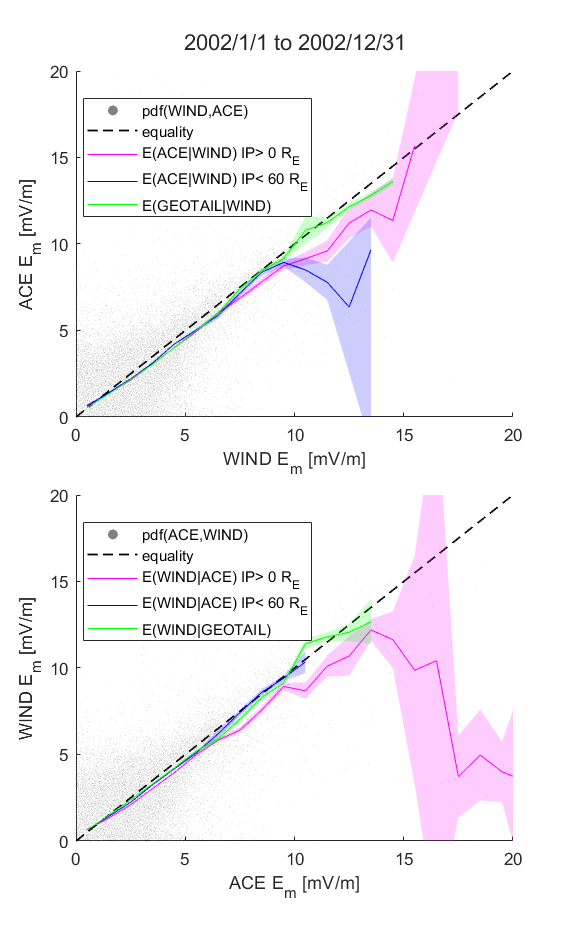

fig5 = figure;
resize_figure(fig5,200,120);
t5 = tiledlayout(2,1,"TileSpacing","compact");

xBin1=0:1:40;
title(t5,'2002/1/1 to 2002/12/31');

nexttile
[p1,p2,p3]=plot_type1(windEm,'WIND',aceEm,'ACE',E_aEm_g_wEm,'E_m [mV/m]',xBin1);
hold on;
p4 = plot_curve(E_aEm_g_wEm1,'b');
hold on;
p5 = plot_curve(E_gEm_g_wEm,'g');
legend([p1,p2,p3,p4,p5],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E','E(GEOTAIL|WIND)'})
xlim([0,20]);
ylim([0,20]);

nexttile
[p1,p2,p3]=plot_type1(aceEm,'ACE',windEm,'WIND', E_wEm_g_aEm,'E_m [mV/m]',xBin1);
hold on;
p4 = plot_curve(E_wEm_g_aEm1,'b');
hold on;
p5 = plot_curve(E_wEm_g_gEm,'g');
legend([p1,p2,p3,p4,p5],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E','E(WIND|GEOTAIL)'})
xlim([0,20]);
ylim([0,20]);

if setExportFig
export_fig([outputFolder,'FigureS2.png'], ...
    '-r600','-png','-nocrop',fig5);
export_fig([outputFolder,'FigureS2.pdf'], ...
    '-r600','-pdf','-nocrop',fig5);
end

## Fig 12: Solar wind driver function $E_{sw}=$-$V_{sw}$ $B_z$ 

yr=2002;
indices.aceTime = find((ace.datetime>=datetime(yr,1,1))&(ace.datetime<datetime(yr+1,12,31)));
indices.windTime = find((wind.datetime>=datetime(yr,1,1))&(wind.datetime<datetime(yr+1,12,31)));

% indices.windTime1 = find((wind.datetime>=datetime(2005,1,1))&(wind.datetime<datetime(2005,12,31)));
% indices.geoTime1 = find((geotail.datetime>=datetime(2005,1,1))&(geotail.datetime<datetime(2005,12,31)));

aceEs = -ace.E_sw(intersect(indices.awI,indices.aceTime),:).*10^-3;
windEs = -wind.E_sw(intersect(indices.waI,indices.windTime),:).*10^-3;
% aceByz = ace.ByGSM(indices.awI,:)./ace.BzGSM(indices.awI,:);
% windByz = wind.ByGSM(indices.waI,:)./wind.BzGSM(indices.waI,:);

% geoEs1 = -geotail.E_kl(intersect(indices.gwI,indices.geoTime1),:).*10^-3;
% windEs1 = -wind.E_kl(intersect(indices.wgI,indices.windTime1),:).*10^-3;

xBin1=0:0.5:30;

E_wEs_g_aEs = create_curve(windEs,aceEs,xBin1);
E_aEs_g_wEs = create_curve(aceEs,windEs,xBin1);

% E_wEs_g_gEs = create_curve(windEs1,geoEs1,xBin1);
% E_gEs_g_wEs = create_curve(geoEs1,windEs1,xBin1);


% Calculating impact parameter
relXGSE = -ace.X_GSE(intersect(indices.awI,indices.aceTime),:)+wind.X_GSE(intersect(indices.waI,indices.windTime),:);
relYGSE = -ace.Y_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Y_GSE(intersect(indices.waI,indices.windTime),:);
relZGSE = -ace.Z_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Z_GSE(intersect(indices.waI,indices.windTime),:);

%SQRT {[Yi-Yj + (Xi-Xj)/13]**2 + (Zi-Zj)**2} https://omniweb.gsfc.nasa.gov/ftpbrowser/impact_ii.html
Dij = sqrt((relYGSE + relXGSE./13).^2 + relZGSE.^2);

E_wEs_g_aEs1 = create_curve(windEs(Dij<60),aceEs(Dij<60),xBin1);
E_aEs_g_wEs1 = create_curve(aceEs(Dij<60),windEs(Dij<60),xBin1);

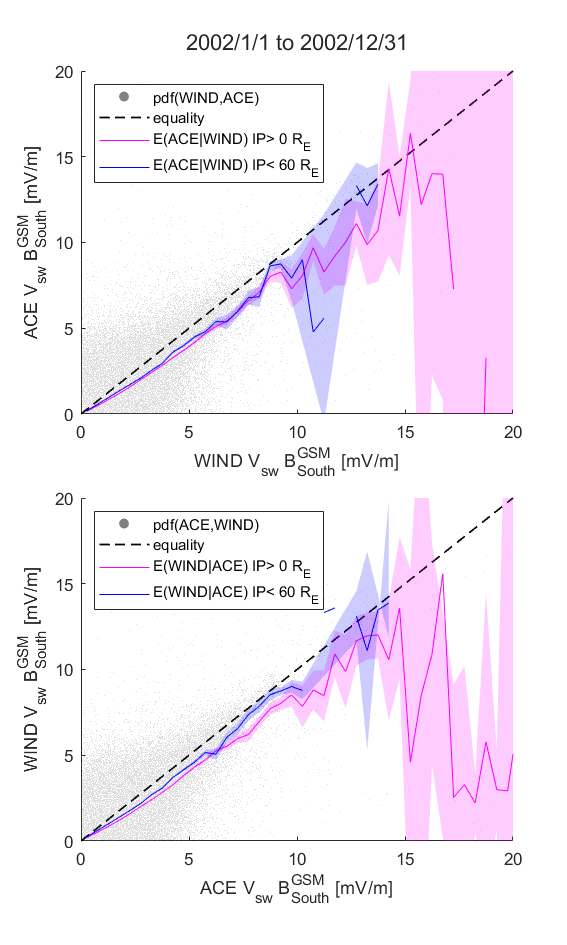

fig6 = figure;
resize_figure(fig6,200,120);
t6 = tiledlayout(2,1,"TileSpacing","compact");

xBin1=0:0.5:30;
title(t6,'2002/1/1 to 2002/12/31');

nexttile
[p1,p2,p3]=plot_type1(windEs,'WIND',aceEs,'ACE',E_aEs_g_wEs,'V_{sw} B^{GSM}_{South} [mV/m]',xBin1);
hold on;
p4 = plot_curve(E_aEs_g_wEs1,'b');
% hold on;
% p5 = plot_curve(E_gEs_g_wEs,'b');
legend([p1,p2,p3,p4],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E'},'Location','northwest');
xlim([0,20]);
ylim([0,20]);

nexttile
[p1,p2,p3]=plot_type1(aceEs,'ACE',windEs,'WIND', E_wEs_g_aEs,'V_{sw} B^{GSM}_{South} [mV/m]',xBin1);
hold on;
p4 = plot_curve(E_wEs_g_aEs1,'b');
% hold on;
% p5 = plot_curve(E_wEs_g_gEs,'b');
legend([p1,p2,p3,p4],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E'},'Location','northwest');
xlim([0,20]);
ylim([0,20]);


disp(['IP > 60 RE = ',num2str(100.*sum(Dij>60)./sum(~isnan(Dij)),2),'% of data points']);

IP > 60 RE = 69% of data points


disp(['IP < 60 RE = ',num2str(100.*sum(Dij<60)./sum(~isnan(Dij)),2),'% of data points']);

IP < 60 RE = 31% of data points


Spacecrafts are far away rather than nearby most of the time. 

if setExportFig
export_fig([outputFolder,'FigureM6_1.png'], ...
    '-r600','-png','-nocrop',fig6);
export_fig([outputFolder,'FigureM6_1.pdf'], ...
    '-r600','-pdf','-nocrop',fig6);
end

xBin1=-30:0.5:30;

E_wEsf_g_aEsf = create_curve(windEs,aceEs,xBin1);
E_aEsf_g_wEsf = create_curve(aceEs,windEs,xBin1);

% E_wEs_g_gEs = create_curve(windEs1,geoEs1,xBin1);
% E_gEs_g_wEs = create_curve(geoEs1,windEs1,xBin1);


% Calculating impact parameter
relXGSE = -ace.X_GSE(intersect(indices.awI,indices.aceTime),:)+wind.X_GSE(intersect(indices.waI,indices.windTime),:);
relYGSE = -ace.Y_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Y_GSE(intersect(indices.waI,indices.windTime),:);
relZGSE = -ace.Z_GSE(intersect(indices.awI,indices.aceTime),:)+wind.Z_GSE(intersect(indices.waI,indices.windTime),:);

%SQRT {[Yi-Yj + (Xi-Xj)/13]**2 + (Zi-Zj)**2} https://omniweb.gsfc.nasa.gov/ftpbrowser/impact_ii.html
Dij = sqrt((relYGSE + relXGSE./13).^2 + relZGSE.^2);

E_wEsf_g_aEsf1 = create_curve(windEs(Dij<60),aceEs(Dij<60),xBin1);
E_aEsf_g_wEsf1 = create_curve(aceEs(Dij<60),windEs(Dij<60),xBin1);

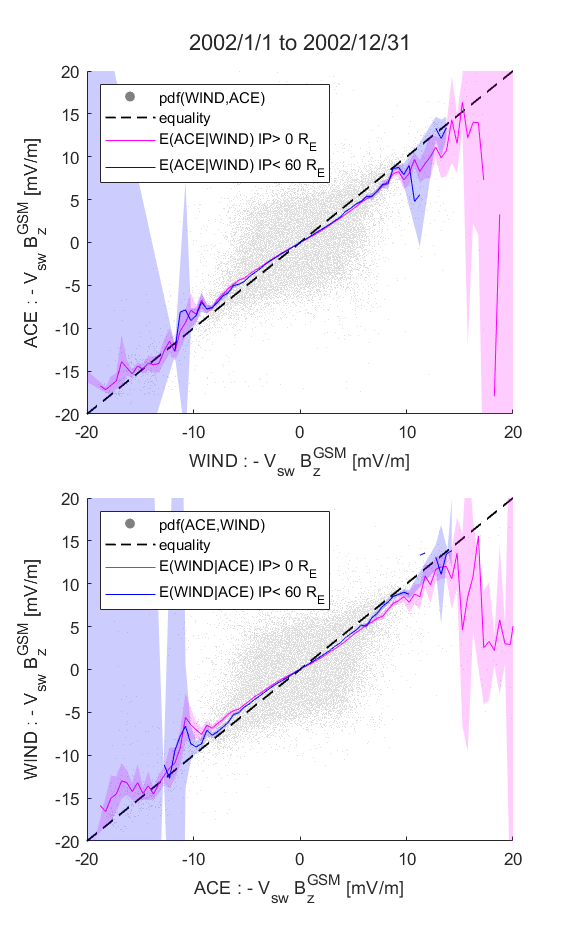

figS2 = figure;
resize_figure(figS2,200,120);
t6 = tiledlayout(2,1,"TileSpacing","compact");

xBin1=-30:0.5:30;
title(t6,'2002/1/1 to 2002/12/31');

nexttile
[p1,p2,p3]=plot_type1(windEs,'WIND',aceEs,'ACE',E_aEsf_g_wEsf,': - V_{sw} B^{GSM}_{z} [mV/m]',xBin1);
hold on;
p4 = plot_curve(E_aEsf_g_wEsf1,'b');
% hold on;
% p5 = plot_curve(E_gEs_g_wEs,'b');
legend([p1,p2,p3,p4],{'pdf(WIND,ACE)','equality','E(ACE|WIND) IP> 0 R_E','E(ACE|WIND) IP< 60 R_E'},'Location','northwest');
xlim([-20,20]);
ylim([-20,20]);

nexttile
[p1,p2,p3]=plot_type1(aceEs,'ACE',windEs,'WIND', E_wEsf_g_aEsf,': - V_{sw} B^{GSM}_{z} [mV/m]',xBin1);
hold on;
p4 = plot_curve(E_wEsf_g_aEsf1,'b');
% hold on;
% p5 = plot_curve(E_wEs_g_gEs,'b');
legend([p1,p2,p3,p4],{'pdf(ACE,WIND)','equality','E(WIND|ACE) IP> 0 R_E','E(WIND|ACE) IP< 60 R_E'},'Location','northwest');
xlim([-20,20]);
ylim([-20,20]);

if setExportFig
export_fig([outputFolder,'FigureS3.png'], ...
    '-r600','-png','-nocrop',figS2);
export_fig([outputFolder,'FigureS3.pdf'], ...
    '-r600','-pdf','-nocrop',figS2);
end

## Functions

function [p1,p2,p3]=plot_type1(sat1,label1,sat2,label2,expectation1,unitLabel,xBin)
    p1 = scatter(sat1,sat2,0.1,0.5.*[1 1 1],'filled');
    hold on;
    p2 = plot(xBin, xBin, '--k','LineWidth',1);
    hold on;
    p3 = plot_curve(expectation1,'m');
    xlabel([label1,' ',unitLabel]);
    ylabel([label2,' ',unitLabel]);
    xlim([min(xBin),max(xBin)]);
    ylim([min(xBin),max(xBin)]);
    legend([p1,p2,p3],{['pdf(',label1,',',label2,')'],'equality',['E(',label2,'|',label1,')']},'Location','best')
end

function [wind,ace,geotail,indices] = initialize_spacecrafts(omniDataFolder)

wind = extract_set_of_data(omniDataFolder,'wind');
ace = extract_set_of_data(omniDataFolder,'ace');
geotail = extract_set_of_data(omniDataFolder,'geotail');

[~,awI,waI]=intersect(ace.datetime,wind.datetime);
indices.awI = awI;
indices.waI = waI;
[~,gwI,wgI]=intersect(geotail.datetime,wind.datetime);
indices.gwI = gwI;
indices.wgI = wgI;

end

function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function [p,c] = plot_2D_error(Y,X,P,yLabel)
    p = pcolor(Y,X,P);
    set(p,'EdgeColor','none');
    c=colorbar_thin('YLabel',yLabel);
end

function curve = create_curve(Y, X, Ei, type)
% Y - first variable, X - second variable, Ei - bin array
% type =2 => use directional statistics
if nargin<4
    type =1; %default
end

if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);
if type==1
    for i = 1:max(xindx)
        curve.YgX(i) = nanmean(Y(xindx==i));
        curve.stdYgX(i) = nanstd(Y(xindx==i));
        curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
        curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
        curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
        curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
        curve.XBins(i) = 0.5*(E(i)+E(i+1));
    end
elseif type==2
    for i = 1:max(xindx)
        curve.YgX(i) = circ_mean(Y(xindx==i)); %radians
        curve.stdYgX(i) = circ_std(Y(xindx==i));
        curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
        curve.SEM(i) = circ_std(Y(xindx==i))./sqrt(curve.NSamples(i));
        curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
        curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
        curve.XBins(i) = 0.5*(E(i)+E(i+1));
    end
else
    error("Wrong type");
end
curve.E = E; 

end


function T1 = extract_data(loadFile)
        % Extract solar wind data from OMNI High Resolution space-craft specific files
        format = '%4f %4f %3f %3f %4f %4f %4.1f %6f %6.2f %6.2f %6.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %6.2f %8.2f %8.2f %4f %8.1f %8.1f %8.1f %8.1f %7.2f %9.0f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %7f';
        tempData = load_ascii_files(loadFile, format, 0);
        T.datetime = datetime(tempData{1},1,tempData{2},tempData{3},tempData{4},zeros(size(tempData{4})));
        T.timeshift = tempData{8}; T.timeshift(T.timeshift==999999) = nan;
        T.BxGSM = tempData{13};  T.BxGSM(T.BxGSM > 9999) = nan;
        T.ByGSM = tempData{16}; T.ByGSM(T.ByGSM > 9999) = nan;
        T.BzGSM = tempData{17}; T.BzGSM(T.BzGSM > 9999) = nan;
        T.velocity = tempData{23}; T.velocity(T.velocity > 99999) = nan;
        T.VxGSE = tempData{24}; T.VxGSE(T.VxGSE>99999) = nan;
        T.VyGSE = tempData{25}; T.VyGSE(T.VyGSE>99999) = nan;
        T.VzGSE = tempData{26}; T.VzGSE(T.VzGSE>99999) = nan;
        T.density = tempData{27}; T.density(T.density>999) = nan;
        T.temperature = tempData{28}; T.temperature(T.temperature>=9999999) = nan;
        T.X_GSE = tempData{29}; T.X_GSE(T.X_GSE>999) = nan;
        T.Y_GSE = tempData{30}; T.Y_GSE(T.Y_GSE>999) = nan;
        T.Z_GSE = tempData{31}; T.Z_GSE(T.Z_GSE>999) = nan;
        T.B_T = (T.ByGSM.^2 + T.BzGSM.^2).^0.5;
%         T.theta_kl = wrapTo2Pi(atan2(T.B_T,T.BzGSM));
        T.theta_kl = wrapTo2Pi(atan2(T.ByGSM,T.BzGSM));
        T.E_kl = T.velocity.*T.B_T.*(sin(T.theta_kl/2)).^2;
        T.E_sw = T.velocity.*T.BzGSM;
        T1 = struct2table(T);
end

function T = extract_set_of_data(loadFolder,satellite)
    fileStr = get_files_in_folder(loadFolder,[satellite,'_min_b*.txt']);
    for i=1:1:length(fileStr)
        T1 = extract_data([loadFolder,fileStr{i}]);
        if i==1
            T=T1;
        else
            T = [T;T1];
        end
    end
end

function data=load_ascii_files(loadFile, format, headerlines)
if nargin<3
    headerlines = 1;
end
fileID = fopen(loadFile,'r');
data = textscan(fileID, format, 'headerlines', headerlines);
fclose(fileID);
end

## External Functions

Acknowledging the use of these external functions: 

1) *Circular Statistics Toolbox (Directional Statistics) *[[Link]](https://www.mathworks.com/matlabcentral/fileexchange/10676-circular-statistics-toolbox-directional-statistics) P. Berens, CircStat: A Matlab Toolbox for Circular Statistics, Journal of Statistical Software, Volume 31, Issue 10, 2009 [http://www.jstatsoft.org/v31/i10](http://www.jstatsoft.org/v31/i10)